# Visualize vehicle trajectories with Birdeye Scope

First, simulate the vehicles' driving scenario in MOBATSim. The birdeye scope doesn't allow the vehicle to stay on halt. So we define the driving scenario as:

startingPoints =    [84 86 15 15 15 15 15 15 15 15];
destinationPoints = [83 51 14 14  14  14 14 14 14 14];
maxSpeeds = [7 20 8 10 14 20 10 12 10 10];

ToWorkspace block need to be added to Vehicle 1 and vehicle 2 in Vehicle Kinematic 3DOF Single Track block:

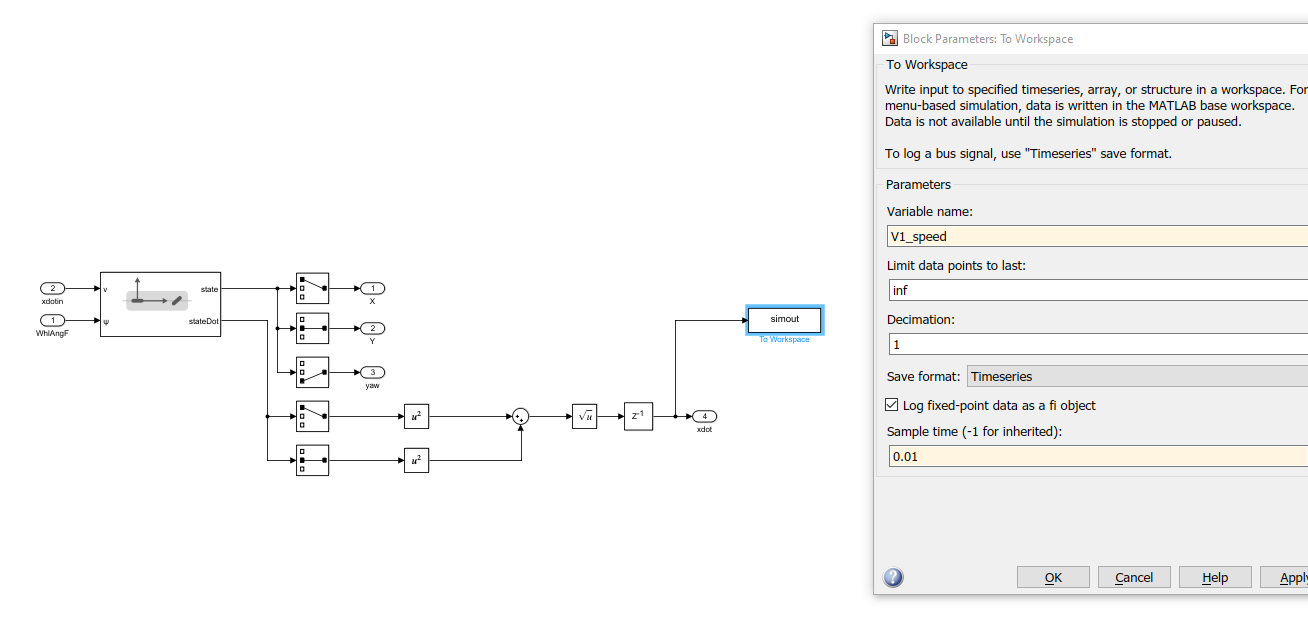

Then run the simulation, stop time is 40s.

After simulation is done, save workspace under the same folder with 'DrivingScenarioDesigner.m' with name 'data'.

Go into 'DrivingScenarioDesigner.m', replace line 597 'temp = evalin('base','ans');' with load('ans.mat');

load('data.mat');
% temp = evalin('base','ans');

Delete all 'temp.'

egoVehicle = vehicle(scenario, ...
    'ClassID', 2, ...
    'Position', [-V2_translation.Data(1,3) -V2_translation.Data(1,1) 0]);
waypoints = [-V2_translation.Data((1:step_length:end),3) -V2_translation.Data((1:step_length:end),1) V2_translation.Data((1:step_length:end),2)];
speed = V2_speed.Data(1:step_length:end);
trajectory(egoVehicle, waypoints, speed);

Next, open ScenarioAnimation.slx and Bird's-Eye Scope App. Trajectories are visualized.